# Simulating effect on EEG leadfields with scalp perforations

### Imports

addpath("/d/gmi/1/simeon/simul_scalp/fieldtrip")
addpath("/d/gmi/1/simeon/simul_scalp/fieldtrip/external/spm12")
addpath("/d/gmi/1/simeon/hsc-eeg-tools/MATLAB")
ft_defaults

### Load headmodel

clear
load fieldtrip/template/headmodel/standard_seg.mat

### Check segmentation

the input is segmented volume data with dimensions [181 217 181]
the volume of each of the segmented compartments in "seg" is


 In fixsegmentation at line 20
 In ft_checkdata>print_segmentedvolumes at line 1852
 In ft_checkdata at line 217
 In ft_sourceplot at line 284

tissue 1        :     1487 ml ( 20.91 %)
tissue 2        :      454 ml (  6.39 %)
tissue 3        :     2048 ml ( 28.81 %)
total segmented :     3989 ml ( 56.11 %)
total volume    :     7109 ml (100.00 %)


 In fixsegmentation at line 20
 In ft_datatype_segmentation at line 173
 In ft_checkdata at line 285
 In ft_sourceplot at line 284

scaling anatomy to [0 1]
not applying a mask on the functional data
not using an atlas
not using a region-of-interest
click left mouse button to reposition the cursor
click and hold right mouse button to update the position while moving the mouse
use the arrowkeys to navigate in the current axis
the call to "ft_sourceplot" took 1 seconds and required the additional allocation of an estimated 81 MB


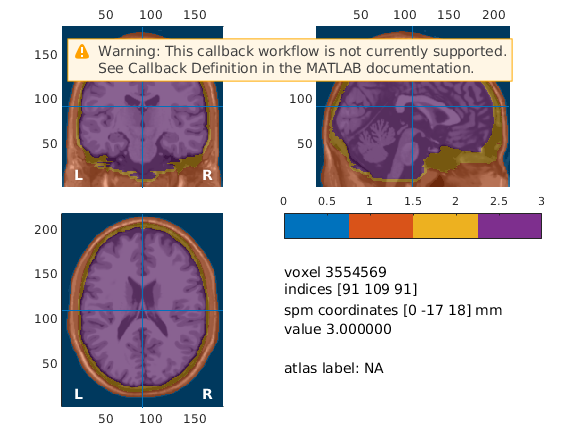

cfg              = [];
cfg.funparameter = 'seg';
cfg.funcolormap  = lines(4); % distinct color per tissue
cfg.location     = 'center';
ft_sourceplot(cfg, mri)

### Generate hexahedral mesh

cfg        = [];
cfg.shift  = 0.3;
cfg.method = 'hexahedral';
cfg.datatype = 'indexed';
hex_mesh = ft_prepare_mesh(cfg, mri);

 In fixsegmentation at line 20
 In ft_datatype_segmentation at line 173
 In ft_checkdata at line 285
 In prepare_mesh_hexahedral at line 18
 In ft_prepare_mesh at line 170

using the field "seg" with the segmented tissue types tissue 1, tissue 2 and tissue 3
Created elements...
Created nodes...
Applying shift 0.300000
the call to "ft_prepare_mesh" took 12 seconds and required the additional allocation of an estimated 430 MB



% fill in missing labels
hex_mesh.tissuelabel = {'scalp', 'skull', 'brain'};

### Load scalp and SEEP electrode locations

% load 10-20 electrodes
elec = ft_read_sens('standard_1020.elc');

% load sample pt localized electrodes
coords = readtable("/d/gmi/r1/CLAS/018/018.labels.csv");
coords = coords(strcmp(coords.Type, 'SEEG'), :);

seeg_sens = [];
seeg_sens.label = coords.Label;
seeg_sens.chanpos = [coords.LocX, coords.LocY, coords.LocZ];
seeg_sens.elecpos = seeg_sens.chanpos;
seeg_sens.unit = 'mm';

### **Verify alignments**

figure;
hold on
ft_plot_mesh(hex_mesh,'surfaceonly','yes','vertexcolor','none','edgecolor','none','facecolor',[0.5 0.5 0.5],'facealpha',0.3)
camlight
ft_plot_sens(elec, 'style', 'b.');

orienting some EEG electrodes along the z-axis


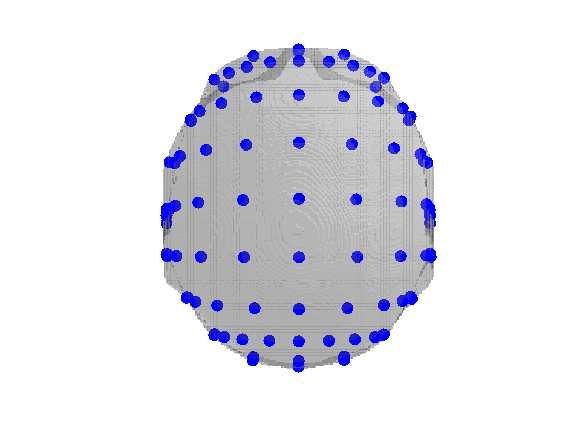

% ft_plot_sens(seeg_sens, 'style', 'b.');
view([0, 90])

exportgraphics(gcf, 'headmesh_eeg.png', 'Resolution',600)

### Poke holes into the scalp

BURRHOLE_SIZE = 1.5;   % in mm

% get unique electrode names
electrode_name = coords.Label(strcmp(coords.Type, 'SEEG'));
for e = 1:length(electrode_name)
    tmp = regexp(electrode_name{e}, '^([A-Za-z]*)[0-9]*$', 'tokens');
    electrode_name{e} = tmp{1}{1};
end
unique_seeg = unique(electrode_name);

hex_mesh_holey = hex_mesh;

for uu = 1:length(unique_seeg)
    curr_chans = cellfun(@(x) startsWith(x, unique_seeg{uu}), coords.Label);

    % draw line through localized electrodes through to scalp
    line_interc = mean(seeg_sens.chanpos(curr_chans,:), 1);
    A = seeg_sens.chanpos(curr_chans,:) - line_interc;
    [U,S,~] = svd(A');
    line_slope = U(:,1);
    t = line_slope'*A';
    t1 = min(t);
    t2 = max(t);

    ln = line_interc' + [t1,t2] .* line_slope; % size 3x2

    % plot to check
%     figure;
%     hold on
%     plot3(seeg_sens.chanpos(curr_chans,1), seeg_sens.chanpos(curr_chans,2), seeg_sens.chanpos(curr_chans,3), 'o')
%     plot3(ln(1,:), ln(2,:), ln(3,:), 'r')
% 
%     title([unique_seeg{uu}, ' line fit'])

    % manually set where bone to CSF
    skull_idx = find(strcmp(hex_mesh.tissuelabel, 'skull'));
    if any(strcmp(hex_mesh.tissuelabel, 'csf'))
        csf_idx = find(strcmp(hex_mesh.tissuelabel, 'csf'));
    elseif any(strcmp(hex_mesh.tissuelabel, 'brain'))
        csf_idx = find(strcmp(hex_mesh.tissuelabel, 'brain'));
    else
        error('No brain-equivalent tissue type found');
    end

    % get middle of hex from position
    skh = find(hex_mesh.tissue == skull_idx);

    n_changed = 0;
    distances = zeros(size(hex_mesh.tissue));

    for kk = 1:length(skh)
        hex_pos = mean(hex_mesh.pos(hex_mesh.hex(skh(kk), :), :), 1);

        % how close to line
        b = line_interc - hex_pos;
        distance_to_line = norm(cross(line_slope, b)) / norm(line_slope);
        distances(skh(kk)) = distance_to_line;

        if distance_to_line < (BURRHOLE_SIZE / 2)
%             hex_mesh_holey.tissue(skh(kk)) = csf_idx;
            hex_mesh_holey.tissue(skh(kk)) = 4;
            n_changed = n_changed + 1;
        end
    end

    fprintf('Changed %d hexes to csf.', n_changed)
    fprintf('Closest hex is %.3f mm away.', min(distances(distances > 0)))
end

Changed 15 hexes to csf.

Closest hex is 0.344 mm away.

Changed 10 hexes to csf.

Closest hex is 0.089 mm away.

Changed 20 hexes to csf.

Closest hex is 0.042 mm away.

Changed 14 hexes to csf.

Closest hex is 0.137 mm away.

Changed 16 hexes to csf.

Closest hex is 0.169 mm away.

Changed 12 hexes to csf.

Closest hex is 0.229 mm away.

Changed 17 hexes to csf.

Closest hex is 0.078 mm away.

Changed 16 hexes to csf.

Closest hex is 0.108 mm away.

Changed 18 hexes to csf.

Closest hex is 0.121 mm away.

Changed 11 hexes to csf.

Closest hex is 0.237 mm away.


hex_mesh_holey.tissuelabel{4} = 'holes';

### PLOT: perforated and non-perforated headmodels

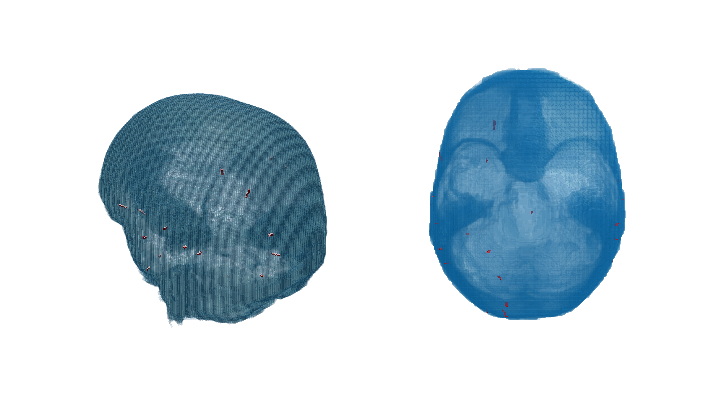

hf = figure;
hf.Position = [100 100 1280 720];

% hax = subplot(1, 2, 1);
% sk_hex_mesh = hex_mesh;
% sk_hex_mesh.hex = sk_hex_mesh.hex(sk_hex_mesh.tissue == skull_idx, :);
% ft_plot_mesh(sk_hex_mesh, ...
%     'surfaceonly', false, ...
%     'vertexcolor', 'none', ...
%     'edgecolor', 'none', ...
%     'facecolor', '#0072BD', ...
%     'facealpha', 0.1);
% camlight
% % view([-180, 90])
% view([-42 39])

hax = subplot(1, 2, 1);
sk_hex_mesh = hex_mesh_holey;
sk_hex_mesh.hex = sk_hex_mesh.hex(sk_hex_mesh.tissue == skull_idx, :);
ft_plot_mesh(sk_hex_mesh, ...
    'surfaceonly', false, ...
    'vertexcolor', 'none', ...
    'edgecolor', 'none', ...
    'facecolor', '#0072BD', ...
    'facealpha', 0.1);
hold on
sk_hex_mesh = hex_mesh_holey;
sk_hex_mesh.hex = sk_hex_mesh.hex(sk_hex_mesh.tissue == 4, :);
ft_plot_mesh(sk_hex_mesh, ...
    'surfaceonly', false, ...
    'vertexcolor', 'none', ...
    'edgecolor', 'none', ...
    'facecolor', '#FF0000', ...
    'facealpha', 1);
camlight
% view([-180, 90])
view([-42 39])

hax = subplot(1, 2, 2);
sk_hex_mesh = hex_mesh_holey;
sk_hex_mesh.hex = sk_hex_mesh.hex(sk_hex_mesh.tissue == skull_idx, :);
ft_plot_mesh(sk_hex_mesh, ...
    'surfaceonly', false, ...
    'vertexcolor', 'none', ...
    'edgecolor', 'none', ...
    'facecolor', '#0072BD', ...
    'facealpha', 0.1);
hold on
sk_hex_mesh = hex_mesh_holey;
sk_hex_mesh.hex = sk_hex_mesh.hex(sk_hex_mesh.tissue == 4, :);
ft_plot_mesh(sk_hex_mesh, ...
    'surfaceonly', false, ...
    'vertexcolor', 'none', ...
    'edgecolor', 'none', ...
    'facecolor', '#FF0000', ...
    'facealpha', 1);
view([0, 90])
camlight
% view([-42 39])

exportgraphics(hf, 'headmesh_burrholes.png', 'Resolution', 600)

### COMPUTE: Generate headmodels using Simbio

conductivities = struct('gray', 0.33, 'white', 0.14, 'csf', 1.79, 'brain', 1.5, 'skull', 0.01, 'scalp', 0.43, 'holes', 1.79);  % check brain

if ~exist('headmodels.mat', 'file')
    cfg        = [];
    cfg.method = 'simbio';
    cfg.conductivity = cellfun(@(x) conductivities.(x), hex_mesh.tissuelabel);

    headmodel_orig  = ft_prepare_headmodel(cfg, hex_mesh);

    cfg.conductivity = cellfun(@(x) conductivities.(x), hex_mesh_holey.tissuelabel);
    headmodel_hole  = ft_prepare_headmodel(cfg, hex_mesh_holey);

    save('headmodels.mat', 'headmodel_orig', 'headmodel_hole');
else
    load('headmodels.mat')
end

### Simulate leadfield

% run forward model on original from AAL and SEEG electrode locations
% cfg                 = [];
% cfg.method = 'basedonvol';
%
% sourcemodel         = ft_prepare_sourcemodel(cfg);
% sourcemodel_orig    = ft_convert_units(sourcemodel, headmodel_orig.unit);
cfg = [];
cfg.elec = elec;
cfg.resolution = 5;

if ~exist('sourcemodel_orig.mat', 'file')
    cfg.headmodel = headmodel_orig;
    sourcemodel_orig = ft_prepare_leadfield(cfg);
    save('sourcemodel_orig.mat', 'sourcemodel_orig')
else
    load('sourcemodel_orig.mat')
end

% run forward model on edited head model from AAL and SEEG electrode
% locations
if ~exist('sourcemodel_hole.mat', 'file')
    cfg.headmodel = headmodel_hole;
    sourcemodel_hole = ft_prepare_leadfield(cfg);
    save('sourcemodel_hole.mat', 'sourcemodel_hole')
else
    load('sourcemodel_hole.mat')
end


Which leadfield positions are available in both leadfield models?

dhole = cellfun(@(x) ~isempty(x), sourcemodel_hole.leadfield);
dorig = cellfun(@(x) ~isempty(x), sourcemodel_orig.leadfield);

dcommon = dhole & dorig;
dcommon = find(dcommon);

Generate single shell headmodel to compute tangential / radial orientations

cfg = [];
cfg.method = 'singlesphere';
cfg.tissue = 'skull';
single_sphere = ft_prepare_headmodel(cfg, hex_mesh);

### How different are the leadfields?

lf_orig = cat(3, sourcemodel_orig.leadfield{dcommon});
lf_hole = cat(3, sourcemodel_hole.leadfield{dcommon});

mean_prc_diff = mean(abs(lf_orig - lf_hole), 'all') / (mean(abs(lf_orig), 'all') + mean(abs(lf_hole), 'all'))
cosine_diff = 1 - dot(lf_orig(:), lf_hole(:)) / (norm(lf_orig(:)) * norm(lf_hole(:)))

### Load epileptic activity

% load background EEG
cfg            = [];
cfg.dataset    = '/d/gmi/r1/iEEG/SEEG-SK-42/SEEG-SK-42.EDF';
cfg.continuous = 'yes';
cfg.channel    = 'eeg1020';
data           = ft_preprocessing(cfg);

Warning OPENEDF: Physical Minimum larger than Maximum.
PLEASE recheck if the scaling and polarity in the following channels are still correct if used:
LAI1 LAI2 LAI3 LAI4 LAI5 LAI6 LAI7 LAI8 LAI9 LAI10 LAI11 LAI12 LAI13 LAI14 C15 C16 C17 C18 C19 C20 LMI1 LMI2 LMI3 LMI4 LMI5 LMI6 LMI7 LMI8 LMI9 LMI10 LMI11 LMI12 LMI13 LMI14 C35 C36 C37 C38 C39 C40 LPI1 LPI2 LPI3 LPI4 LPI5 LPI6 LPI7 LPI8 LPI9 LPI10 LPI11 LPI12 LPI13 LPI14 C55 C56 C57 C58 C59 C60 LAC1 LAC2 LAC3 LAC4 LAC5 LAC6 LAC7 LAC8 LAC9 LAC10 LMC1 LMC2 LMC3 LMC4 LMC5 LMC6 LMC7 LMC8 LMC9 LMC10 LPC1 LPC2 LPC3 LPC4 LPC5 LPC6 LPC7 LPC8 LPC9 LPC10 LOF1 LOF2 LOF3 LOF4 LOF5 LOF6 LOF7 LOF8 LOF9 LOF10 LFL1 LFL2 LFL3 LFL4 LFL5 LFL6 LFL7 LFL8 LFL9 LFL10 LFL11 LFL12 LFL13 LFL14 C115 C116 C117 C118 C119 C120 LSMA1 LSMA2 LSMA3 LSMA4 LSMA5 LSMA6 LSMA7 LSMA8 LSMA9 LSMA10 RAI1 RAI2 RAI3 RAI4 RAI5 RAI6 RAI7 RAI8 RAI9 RAI10 RAI11 RAI12 RAI13 RAI14 C145 C146 C147 C148 C149 C150 RPI1 RPI2 RPI3 RPI4 RPI5 RPI6 RPI7 RPI8 RPI9 RPI10 RPI11 RPI12 RPI13 RPI14 C1

 In read_edf at line 284
 In ft_read_header at line 854
 In ft_preprocessing at line 390

processing channel { 'Fp1' 'F7' 'T3' 'T5' 'O1' 'F3' 'C3' 'P3' 'Fp2' 'F8' 'T4' 'T6' 'O2' 'F4' 'C4' 'P4' 'Fpz' 'Fz' 'Cz' 'Pz' }
reading and preprocessing
reading and preprocessing trial 1 from 1

the call to "ft_preprocessing" took 13 seconds and required the additional allocation of an estimated 341 MB



elec_avail_channels = find(cellfun(@(x) ismember(x, data.label), elec.label));

% load example spikes
spike_data = load_spikes();

Warning OPENEDF: Physical Minimum larger than Maximum.
PLEASE recheck if the scaling and polarity in the following channels are still correct if used:
AD1 AD2 AD3 AD4 AD5 AD6 MD1 MD2 MD3 MD4 MD5 MD6 PD1 PD2 PD3 PD4 PD5 PD6 PD7 PD8 PD9 PD10 IAS1 IAS2 IAS3 IAS4 IAS5 IAS6 IPS1 IPS2 IPS3 IPS4 IPS5 IPS6 LS1 LS2 LS3 LS4 LS5 LS6 C41 C42 C43 C44 C45 C46 C47 C48 C49 C50 C51 C52 C53 C54 C55 C56 C57 C58 C59 C60 C61 C62 C63 C64 C65 C66 C67 C68 C69 C70 C71 C72 C73 C74 C75 C76 C77 C78 C79 C80 C81 C82 C83 C84 C85 C86 C87 C88 C89 C90 C91 C92 C93 C94 C95 C96 C97 C98 C99 C100 C101 C102 C103 C104 C105 C106 C107 C108 C109 C110 C111 C112 C113 C114 C115 C116 C117 C118 C119 C120 C121 C122 C123 LEMG1 LEMG2 REMG1 REMG2 EKG DC1 DC2 DC3 DC4 DC5 DC6 DC7 DC8 DC9 DC10 DC11 DC12 DC13 DC14 DC15 DC16 TRIG Pleth 


 In read_edf at line 284
 In ft_read_header at line 854
 In ft_preprocessing at line 390

processing channel { 'AD1' 'AD2' 'AD3' 'AD4' 'AD5' 'AD6' 'MD1' 'MD2' 'MD3' 'MD4' 'MD5' 'MD6' 'PD1' 'PD2' 'PD3' 'PD4' 'PD5' 'PD6' 'PD7' 'PD8' 'PD9' 'PD10' 'IAS1' 'IAS2' 'IAS3' 'IAS4' 'IAS5' 'IAS6' 'IPS1' 'IPS2' 'IPS3' 'IPS4' 'IPS5' 'IPS6' 'LS1' 'LS2' 'LS3' 'LS4' 'LS6' }
reading and preprocessing
reading and preprocessing trial 1 from 1

the call to "ft_preprocessing" took 1 seconds and required the additional allocation of an estimated 0 MB



% project through leadfield
MNI = [-40, 0, 0]; % move through to z = 55

### Inverse models to create background

Downsample the leadfield so we don't crash MATLAB

cfg = [];

creating sourcemodel based on automatic 3D grid with specified resolution
creating 3D grid with 20 mm resolution
initial 3D grid dimensions are [11 13 11]
selecting dipole positions inside the 'brain' tissue
pruning headmodel volume elements from 3988702 to 2047902 (51%)
pruning headmodel vertices from 4080232 to 2113968 (52%)
pruning dipole positions from 1573 to 504 (32%)
256 dipoles inside, 1317 dipoles outside brain
making tight grid
256 dipoles inside, 248 dipoles outside brain
the call to "ft_prepare_sourcemodel" took 4 seconds and required the additional allocation of an estimated 0 MB


cfg.resolution = 20;
cfg.headmodel = headmodel_orig;
ds_sources = ft_prepare_sourcemodel(cfg);

ds_sources.pos = ds_sources.pos(ds_sources.inside,:);
ds_sources.inside = ds_sources.inside(ds_sources.inside);

% original leadfield
ds_leadfield_orig = sourcemodel_orig;
ds_leadfield_orig.leadfield = cell(1, length(ds_sources.inside));
for kk = 1:length(ds_sources.inside)
    idx = find(all(ds_sources.pos(kk,:) == sourcemodel_orig.pos, 2));
    ds_leadfield_orig.leadfield{kk} = sourcemodel_orig.leadfield{idx};
end
ds_leadfield_orig.pos = ds_sources.pos;
ds_leadfield_orig.inside = ds_sources.inside;
ds_leadfield_orig.dim = ds_sources.dim;

% holey leadfield
ds_leadfield_hole = ds_leadfield_orig;
for kk = 1:length(ds_sources.inside)
    idx = find(all(ds_sources.pos(kk,:) == sourcemodel_hole.pos, 2));
    ds_leadfield_hole.leadfield{kk} = sourcemodel_hole.leadfield{idx};
end

Run inverse

cfg = [];

the input is raw data with 20 channels and 1 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 1 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_timelockanalysis" took 3 seconds and required the additional allocation of an estimated 2367 MB


the input is timelock data with 20 channels and 2212032 timebins
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 1348 MB
using precomputed leadfields
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 1347 MB
scanning repetition 1
using precomputed leadfields
    0.9312

    0.4313

    0.1829

    0.0892

    0.0460

    0.0240

    0.0125

    0.0064

    0.0033

    0.0017

   8.5401e-04

   4.3251e-04

   2.1849e-04

   1.1015e-04

   5.5442e-05

   2.7870e-05

   1.3996e-05

   7.0225e-06

   3.5212e-06

   1.7646e-06

   8.8396e-07

the call to "ft_sourceanalysis" took 4 seconds and required the additional allocation of an estimated 13338 MB


cfg.covariance = 'yes';
tlock = ft_timelockanalysis(cfg, data);

cfg = [];
cfg.method = 'eloreta';
cfg.sourcemodel = ds_leadfield_orig;
cfg.headmodel = headmodel_orig;

source_data = ft_sourceanalysis(cfg, tlock);

Project back to scalp

data_to_1020_lbl = cellfun(@(x) find(strcmp(x, sourcemodel_orig.label)), data.label);

reproj_data_orig = zeros(length(data_to_1020_lbl), length(source_data.time));
for kk = 1:length(data_to_1020_lbl)
    for ss = 1:length(source_data.avg.mom)
        reproj_data_orig(kk,:) = reproj_data_orig(kk,:) + ...
            (source_data.avg.mom{ss}' * ...
            ds_leadfield_orig.leadfield{ss}(data_to_1020_lbl(kk), :)')';
    end
end

reproj_data_hole = zeros(length(data_to_1020_lbl), length(source_data.time));
for kk = 1:length(data_to_1020_lbl)
    for ss = 1:length(source_data.avg.mom)
        reproj_data_hole(kk,:) = reproj_data_hole(kk,:) + ...
            (source_data.avg.mom{ss}' * ...
            ds_leadfield_hole.leadfield{ss}(data_to_1020_lbl(kk), :)')';
    end
end

Plot scalp data and reprojected data to verify

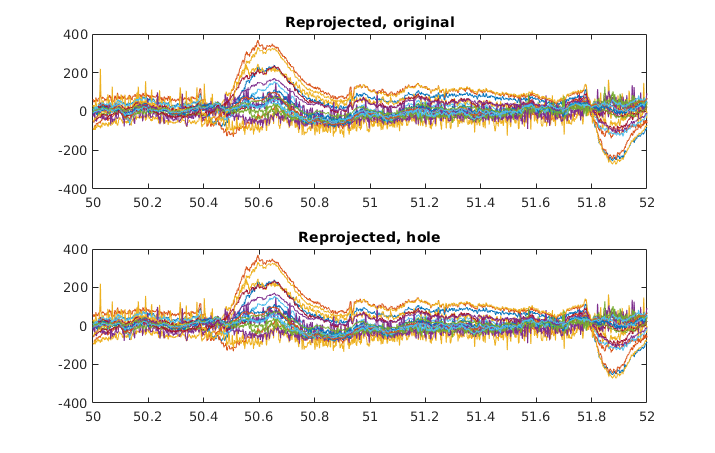

% hf = figure;
% hf.Position = [10, 10, 1500, 950];
% 
% hax = arrayfun(@(x) subplot(2, 1, x), 1:2);
% 
% plot(hax(1), data.time{1}, reproj_data_orig)
% hax(1).Title.String = 'Reprojected';
% 
% plot(hax(2), data.time{1}, data.trial{1})
% hax(2).Title.String = 'Raw data';
% 
% linkaxes(hax, 'x')
% 
% hax(1).XLim = [50 52];

hf = figure;
hf.Position = [10, 10, 1500, 950];

hax = arrayfun(@(x) subplot(2, 1, x), 1:2);

plot(hax(1), data.time{1}, reproj_data_orig)
hax(1).Title.String = 'Reprojected, original';

plot(hax(2), data.time{1}, reproj_data_hole)
hax(2).Title.String = 'Reprojected, hole';

linkaxes(hax, 'x')

hax(1).XLim = [50 52];

### Add spikes to background

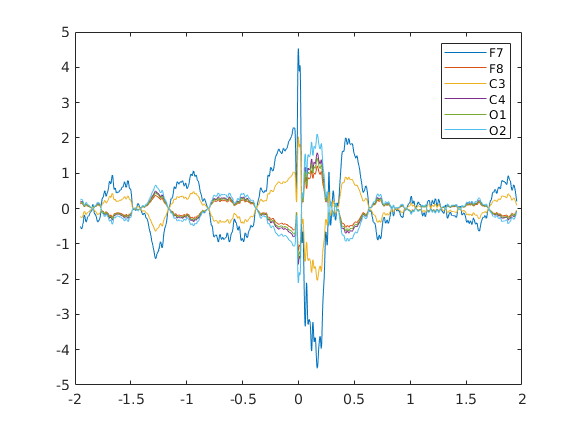

for z = 0 % 0:5:55
    % find the closest point that has been computed
    idx = find(all(sourcemodel_orig.pos == [-30, 0, z], 2));

    if isempty(sourcemodel_orig.leadfield{idx})
        fprintf('Skipping [%.1f, %.1f, %.1f]\n', ...
            sourcemodel_orig.pos(idx,1), ...
            sourcemodel_orig.pos(idx,2), ...
            sourcemodel_orig.pos(idx,3))
        continue
    end

    %%% separate into radial and tangential components
    max_w = mean(sourcemodel_orig.leadfield{idx},1);
    max_w = max_w ./ norm(max_w);

    % radial vector
    radvec = sourcemodel_orig.pos(idx,:) - single_sphere.o;
    radvec = radvec ./ norm(radvec);

    % largest tangential vector
    tanvec = radvec - (dot(max_w, radvec) * radvec);
    tanvec = tanvec ./ norm(tanvec);

    % project through leadfield
    lfrad = sourcemodel_orig.leadfield{idx} * radvec';
    rad_data = spike_data.data .* lfrad .* 200;

    lftan = sourcemodel_orig.leadfield{idx} * tanvec';
    tan_data = spike_data.data .* lftan .* 200;

    n_lf = size(ds_leadfield_orig.leadfield{1}, 1);
    n_sp = size(tan_data,2);
    cproj_data = zeros(n_lf, n_sp);
    for kk = 1:n_lf
        for ss = 1:length(source_data.avg.mom)
            cproj_data(kk,:) = cproj_data(kk,:) + ...
                (source_data.avg.mom{ss}(:,100000+(1:n_sp))' * ...
                ds_leadfield_orig.leadfield{ss}(kk, :)')';
        end
    end
    cproj_data = cproj_data ./ 50;
end


subset_electrodes = {'F7', 'F8', 'C3', 'C4', 'O1', 'O2'};
% subset_to_1020 = cellfun(@(x) find(strcmp(x, data.label)), subset_electrodes);
subset_lbl = cellfun(@(x) find(strcmp(x, sourcemodel_orig.label)), subset_electrodes);

% sum with scalp data
% tan_data = tan_data + reproj_data_orig(subset_to_1020, 1000+(1:size(tan_data,2)));

hf = figure;
plot(spike_data.time, tan_data(subset_lbl, :))
legend(subset_electrodes)

exportgraphics(hf, 'proj_spikeonly.png', 'Resolution', 600)

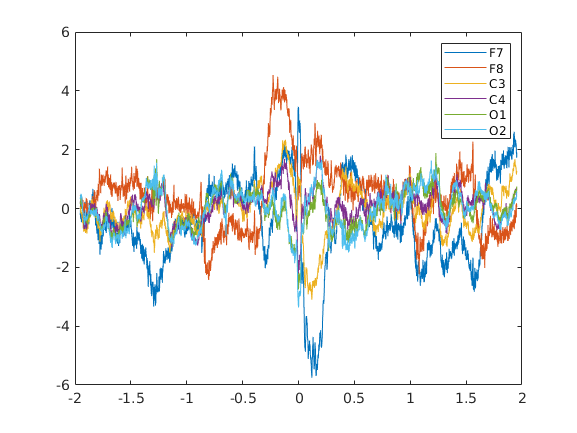



hf = figure;
plot(spike_data.time, tan_data(subset_lbl, :) + cproj_data(subset_lbl, :))
legend(subset_electrodes)

exportgraphics(hf, 'proj_spikebkg.png', 'Resolution', 600)




for z = 0 % 0:5:55
    % find the closest point that has been computed
    idx = find(all(sourcemodel_hole.pos == [-30, 0, z], 2));

    if isempty(sourcemodel_hole.leadfield{idx})
        fprintf('Skipping [%.1f, %.1f, %.1f]\n', ...
            sourcemodel_hole.pos(idx,1), ...
            sourcemodel_hole.pos(idx,2), ...
            sourcemodel_hole.pos(idx,3))
        continue
    end

    %%% separate into radial and tangential components
    max_w = mean(sourcemodel_hole.leadfield{idx},1);
    max_w = max_w ./ norm(max_w);

    % radial vector
    radvec = sourcemodel_hole.pos(idx,:) - single_sphere.o;
    radvec = radvec ./ norm(radvec);

    % largest tangential vector
    tanvec = radvec - (dot(max_w, radvec) * radvec);
    tanvec = tanvec ./ norm(tanvec);

    % project through leadfield
    lfrad = sourcemodel_hole.leadfield{idx} * radvec';
    rad_data = spike_data.data .* lfrad * 200;

    lftan = sourcemodel_hole.leadfield{idx} * tanvec';
    tan_data = spike_data.data .* lftan * 200;

    n_lf = size(ds_leadfield_orig.leadfield{1}, 1);
    n_sp = size(tan_data,2);
    cproj_data = zeros(n_lf, n_sp);
    for kk = 1:n_lf
        for ss = 1:length(source_data.avg.mom)
            cproj_data(kk,:) = cproj_data(kk,:) + ...
                (source_data.avg.mom{ss}(:,100000+(1:n_sp))' * ...
                ds_leadfield_hole.leadfield{ss}(kk, :)')';
        end
    end
    cproj_data = cproj_data ./ 50;
end

% sum with scalp data

subset_electrodes = {'F7', 'F8', 'C3', 'C4', 'O1', 'O2'};
subset_lbl = cellfun(@(x) find(strcmp(x, sourcemodel_hole.label)), subset_electrodes);

hf = figure;
plot(spike_data.time, tan_data(subset_lbl, :))
legend(subset_electrodes)

exportgraphics(hf, 'proj_spikeonly_hole.png', 'Resolution', 600)



hf = figure;
plot(spike_data.time, tan_data(subset_lbl, :) + cproj_data(subset_lbl, :))
legend(subset_electrodes)

exportgraphics(hf, 'proj_spikebkg_hole.png', 'Resolution', 600)




hf = figure;
plot(spike_data.time, cproj_data(subset_lbl, :))
axis off

exportgraphics(hf, 'proj_bkgonly.png', 'Resolution', 600)

implemented above: get direction of max overall power

### How different are the leadfields?

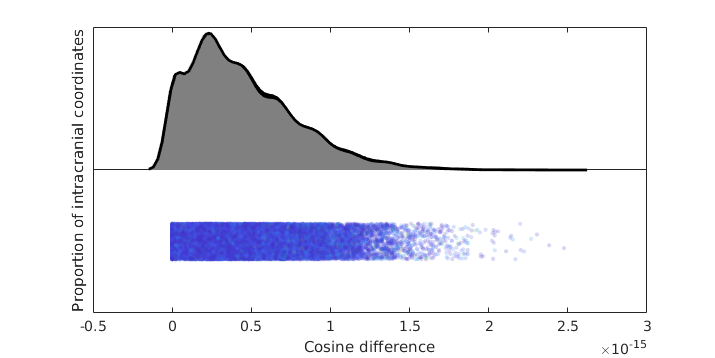

addpath(fullfile(pwd, 'cbrewer2'));
addpath(fullfile(pwd, 'Robust_Statistical_Toolbox', 'graphic_functions'));
addpath(fullfile(pwd, 'RainCloudPlots', 'tutorial_matlab'));

% compute leadfield differences
rel_diff = zeros(length(dcommon), 1);
for kk = 1:length(dcommon)
    lfo = sourcemodel_orig.leadfield{dcommon(kk)};
    lfh = sourcemodel_hole.leadfield{dcommon(kk)};
    rel_diff(kk) = mean(abs(lfo - lfh) ./ ((abs(lfo) + abs(lfh)) / 2), 'all');
end

cos_diff = zeros(length(dcommon), 1);
for kk = 1:length(dcommon)
    lfo = sourcemodel_orig.leadfield{dcommon(kk)};
    lfh = sourcemodel_hole.leadfield{dcommon(kk)};
    cos_diff(kk) = abs(1 - (dot(lfo(:), lfh(:)) / (norm(lfo(:)) * norm(lfh(:)))));
end

% compute distance to scalp
dist_to_scalp = zeros(length(dcommon), 1);
scalp_pts = hex_mesh.pos(hex_mesh.tissue == 1,:);
for kk = 1:length(dcommon)
    dist_to_scalp(kk) = min(rssq(sourcemodel_orig.pos(dcommon(kk), :) - scalp_pts, 2));
end

% raincloud plot
cos_diff_plt = max(0, cos_diff + (randn(size(cos_diff)) * 1.1102e-16 / 1.5));
raincloud_plot(cos_diff_plt, 'scatter_color', dist_to_scalp);
hf = gcf;
hf.Position = [10 10 1000 400];

ax = gca;
ax.YAxis.TickValues = [];
ax.YLabel.String = 'Proportion of intracranial coordinates';
ax.XLabel.String = 'Cosine difference';

hC = colorbar('eastoutside');
hC.Label.String = 'Distance from skull (mm)';

exportgraphics(gcf, 'leadfield_cosdiff.png', 'Resolution', 600)